Material1 = [0.2323; 0.2755; 0.1958; 0.2110; 0.2582; 0.2154];

% 1. Number of samples, n
n_M1 = length(Material1)

n_M1 = 6


% 2. Sample mean, x̄
x_M1 = mean(Material1)

x_M1 = 0.2314


% 3. Sample standard deviation, S
std_M1 = std(Material1)

std_M1 = 0.0303


% 4. The “estimated model error”, the difference between model and experiment means
model_mean = 0.2457

model_mean = 0.2457


model_error = model_mean - x_M1

model_error = 0.0143


% 5. Your +/- bounds with (alpha =.10)
t = tinv(1 - 0.10 / 2, 5)

t = 2.0150


U_limit = x_M1 + t * (std_M1 / sqrt(n_M1))

U_limit = 0.2563


L_limit = x_M1 - t * (std_M1 / sqrt(n_M1))

L_limit = 0.2064


% 7. Calculate the overall model error +/- deviation
Error_Ul = model_error + (t * (std_M1 / sqrt(n_M1)))

Error_Ul = 0.0393

Error_Ll = model_error - (t * (std_M1 / sqrt(n_M1)))

Error_Ll = -0.0106

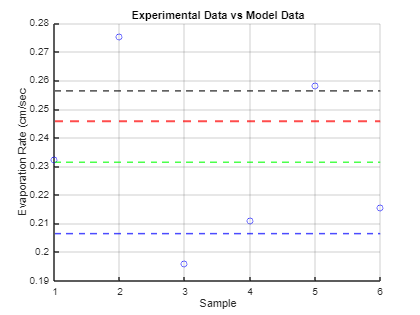


% 6. Plot the experimental data, model and experimental means, upper and lower limits of your model deviation
figure 
hold on 
grid on
plot(1:n_M1, Material1, 'bo')
yline(x_M1, 'g--', 'LineWidth', 1.5, 'DisplayName', 'Experimental Mean')
yline(model_mean, 'r--', 'LineWidth', 2, 'DisplayName', 'Model Mean')
yline(U_limit, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Upper Limit')
yline(L_limit, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Lower Limit')

xlabel('Sample')
ylabel('Evaporation Rate (cm/sec')
title('Experimental Data vs Model Data')

legend()